# Lysosome Display

This live script was used to generate the figures of taste cells with their lysosome 

NOTE: The tables used in this script are generated and/or updated in the companion [**lysosome_get_tables**](matlab:open('./lysosome_get_tables.mlx')) live script

**Additional Requirements:**

- The MatGeom toolbox:  [https://github.com/mattools/matGeom](https://github.com/mattools/matGeom) 

## Initialize functions and load data

setupMatGeom % MatGeom needs to be installed

Installing MatGeom Library
Adding module: geom2d               (ok)
Adding module: polygons2d           (ok)
Adding module: graphs               (ok)
Adding module: polynomialCurves2d   (ok)
Adding module: geom3d               (ok)
Adding module: meshes3d             (ok)
Adding module: utils                (ok)


close all
clearvars

paths.project = "/Users/ernesto/github/Dying_Taste_Cell_analysis";
paths.analysis = fullfile(paths.project,"Lysosome Analysis");
paths.supportfns = fullfile(paths.project,"Support Functions");

paths.manifoldPlus = "/Users/ernesto/github/ManifoldPlus/build/manifold"; % exe file
paths.temp = "/Users/ernesto/Desktop/temp"; % writable location to stash obj files

### Load Data for Plotting

if exist(fullfile(paths.analysis,"lysosomesVL.mat"),"file")
    load(fullfile(paths.analysis,"lysosomesVL.mat")) % load VL
    load(fullfile(paths.analysis,'cellT.mat')) %cellT
    load(fullfile(paths.analysis,"lysT.mat")) %lysT
    idT = VL.Properties.UserData.idT;
end

### Add support functions to path

(if you haven't already added them)

addpath(paths.supportfns,...
    fullfile(paths.supportfns,"colornames"))

## Display

### Set Polarity

cells are randomly orientated after  MatGeom Align to surface function. Polarity helps control for this stochastic process. 

cellT.Polarity = ones(height(cellT),1);

1. TB1_AP13_EM
2. TB1_AP14_EM


cellT.Polarity([1 4 10 11 11 12 13 15 16 17 20 23 25]) = -1; % direction of cell

### Plot Cells Lysosomes Overlays

Organize Cells in one figure (using nexttile)

#### Use Patch

plot_cellT(VL, cellT,'patch');

- Slower

### Use alphaShape

Rendering...
1. TB1_IMMCell09_CM_ry
2. TB1_IMMcell08_CM_RKJ
3. TB2 Nucleus_26_cw_IV-ry
4. TB2_T4C-01_cw
5. TB1_AP31_EM
6. TB2_t3cell02_CM_RSL
7. TB2_T3C-08_cw
8. TB2_T3C-17_cw
9. TB2_T3C-14_FR
10. TB2_T3Cell07_cm_RSL
11. TB1_AP02_EM
12. TB2_T2C-12_cw
13. TB2_T2C-09_cw
14. TB1_AP14_EM
15. TB2_T2Cell03_CM_LES
16. TB2_T2C-10_cw
17. TB1_AP38_EM
18. TB1_AP34_EM
19. TB1_AP36_EM
20. TB2 Nucleus_04_cw_cell-ry
21. TB1_AP16_EM
22. TB1_AP37_EM
23. TB1_AP70_RSL
24. TB2_T1C-05_cw
25. TB2_T1C-06_cw
26. TB2_TCdying-02_cw
27. TB2_TCdying-01_cw
28. TB1_AP44_EM
29. TB1_AP51_EM
30. TB1_AP13_EM
31. TB2_T2C-03_cw
32. TB1_AP40_EM
33. TB2_T2C-01_FR


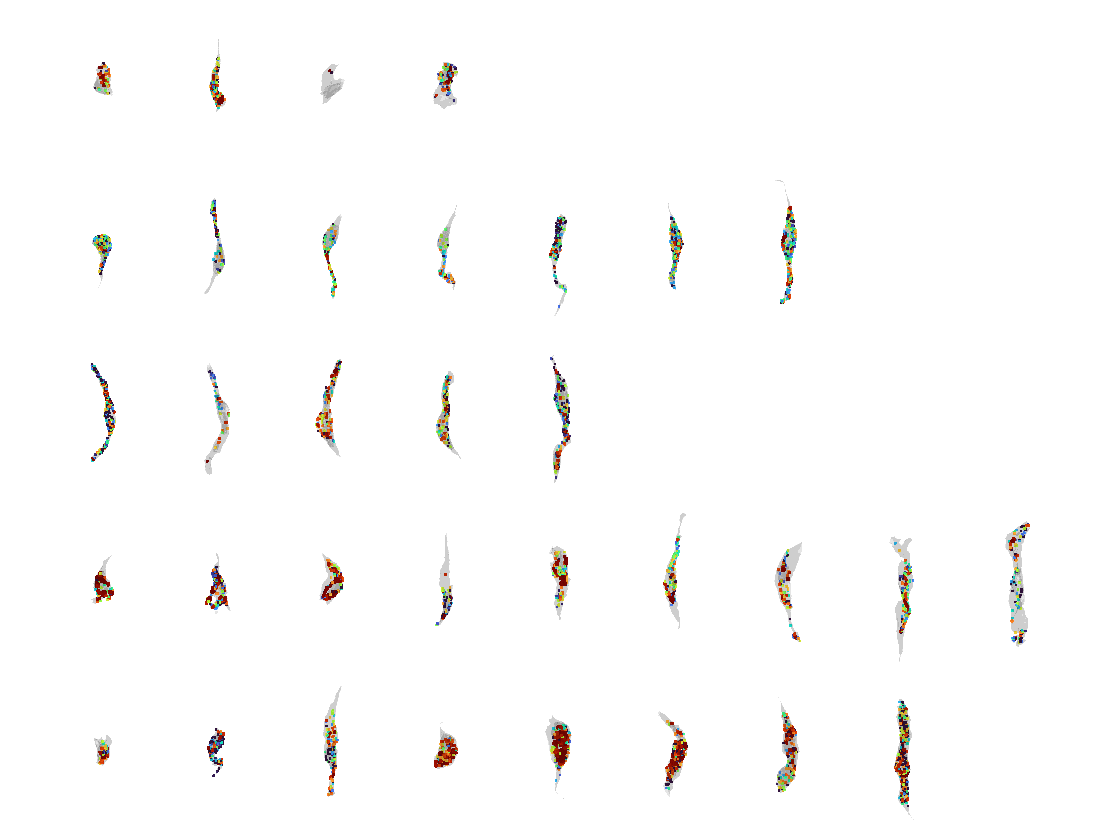

cellT = sortrows(cellT,"VolMan");

mmfig
hp = plot_cellT(VL, cellT,'alphaShape');

## Plot Indicated Cells (and lysosomes)

Here we use the cellT table (or a subset of the table) to indicate which cells to plot

#### Create Figure

mmfig;

- TB1_AP13_EM

- TB1_AP14_EM

NOTE: cells may be plot but be too small to notice at first. Make figure larger to see them

coi = ["TB1_AP13_EM" "TB1_AP14_EM"]; % cells of interest
la = ismember(cellT.Object,coi);
row = find(la);
clf
hp = plot_cellT(VL, cellT(row,:),'alphaShape',false)

### Plot by selected cellT row

mmfig; % create new figure

#### Select Row

clf; % clear figure
row = 18; % select row
hp = plot_cellT(VL, cellT(row,:),'alphaShape',false);

#### Change plot appearance

hp.EdgeColor = 'k'
hp.FaceColor = 'g';
hp.FaceAlpha = 0.9

### Export Figures

exportgraphics(gcf,fullfile(project_folder,"Figures","AP13vAP14.png"),Resolution=300)

exportgraphics(gcf,fullfile(project_folder,"Figures","colorbar.pdf"))

#### Get stats on COI

la = ismember(lysT.Cell,coi);
lt = lysT(la,:);

## Plot Cell Lysosomes by Cell Type

Cell type is a plotted by row in figure

### Set Polarity

cellT.Polarity = ones(height(cellT),1);

- not really using this

#### Plot cells as alpha shapes

figure(Visible="on",WindowStyle="docked")
ax = plot_cellT_tiled(VL,cellT); 